**Arjan Gupta**

Date: *February 21, 2023* 

Assignment: [Major Individual Assignment] Path Planning for Capsule Robot

clear; close all; clc;

# A Probabilistic Model for Demonstrating High Path Planning Success Rate in Autonomous Capsule Robots for Bronchoscopies

### Assesment block

The following code runs 24 trials of the RRT path planning algorithm, implemented as described in the submitted paper.

total_trials = 24;
solutions = 0;

for i = 1:total_trials
    subplot(4,6,i);
    fprintf("Running trial #%d... ", i);
    solutionFound = capsule(i);
    if solutionFound
        solutions = solutions + 1;
    end
    fprintf("\n");
end

Running trial #1... 

Path found.

Running trial #2... 

Path found.

Running trial #3... 

Path found.

Running trial #4... 

Path found.

Running trial #5... 

Path found.

Running trial #6... 

Path found.

Running trial #7... 

Path found.

Running trial #8... 

Path found.

Running trial #9... 

Path found.

Running trial #10... 

Path found.

Running trial #11... 

Path found.

Running trial #12... 

Path found.

Running trial #13... 

Path found.

Running trial #14... 

Path found.

Running trial #15... 

Path found.

Running trial #16... 

Path found.

Running trial #17... 

Path found.

Running trial #18... 

Path found.

Running trial #19... 

Path found.

Running trial #20... 

Path found.

Running trial #21... 

Path found.

Running trial #22... 

Path found.

Running trial #23... 

Path found.

Running trial #24... 

No path solution found.

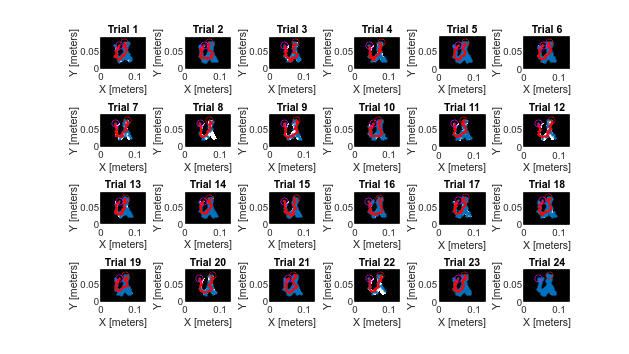

set(gcf, 'Position', get(0, 'Screensize'));


fprintf("Success rate: %f%s\n", 100*(solutions/total_trials), "%");

Success rate: 95.833333%


## **Functions**

#### **Goal Check Callback**

The following code is called by the RRT planning algorithm to check proximity to the goal.

function isReached = checkIfReachedGoal(planner, goalState, newState)
    resolution = 10000;
    isReached = false;
    threshold = 5/resolution;
    if planner.StateSpace.distance(newState, goalState) < threshold
        isReached = true;
    end
end

#### **Path Planning for Capsule Robot**

The following code runs the actual path planning algorithm for the capsule robot.

function solutionFound = capsule(trial_num)

% Default the flag to true
solutionFound = true;

% Load in the airway image, transform to grayscale and invert it
[airway,color_map, transp] = imread("939-Oblique.png");
gray_airway = rgb2gray(airway);
inverted_airway = gray_airway == 0;

% Create occupancy grid
resolution = 10000;
occGrid = binaryOccupancyMap(inverted_airway, resolution);
show(occGrid)

rng shuffle

% Set start and goal poses
start = [randi([685,800])/resolution, 750/resolution, (randi(200)/100)*pi];

% Select left or right narrow airway for the goal
leftorRight = randi(2);
goal = zeros(1,3);
if leftorRight == 1
    goal = [randi([415,445])/resolution, 660/resolution, (randi(200)/100)*pi];
else
    goal = [randi([540,560])/resolution, 660/resolution, (randi(200)/100)*pi];
end

bounds = [occGrid.XWorldLimits; occGrid.YWorldLimits; [-pi pi]];

% Use Reeds Shepp curves for defining state space
capsuleStateSpace = stateSpaceReedsShepp(bounds);
capsuleStateSpace.MinTurningRadius = 20/resolution;

% Plan the path
capsuleStateValidator = validatorOccupancyMap(capsuleStateSpace); 
capsuleStateValidator.Map = occGrid;
capsuleStateValidator.ValidationDistance = 5/resolution;

planner = plannerRRT( ...
    capsuleStateSpace, ...
    capsuleStateValidator);
planner.MaxConnectionDistance = 50/resolution;
planner.MaxIterations = 9000;

planner.GoalReachedFcn = @checkIfReachedGoal;

rng shuffle

[pthObj, solnInfo] = plan(planner,start,goal);

show(occGrid)
hold on

% Plot entire search tree
plot( ...
    solnInfo.TreeData(:,1), ...
    solnInfo.TreeData(:,2),'.-');

if pthObj.NumStates > 0
    % Interpolate and plot path
    interpolate(pthObj,300)
    plot( ...
        pthObj.States(:,1), ...
        pthObj.States(:,2), ...
        'r-','LineWidth',2)
    fprintf("Path found.")
else
    fprintf("No path solution found.")
    solutionFound = false;
end

% Show start and goal in grid map
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')

% Edit title text
title(sprintf("Trial %d", trial_num))
hold off
end